# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

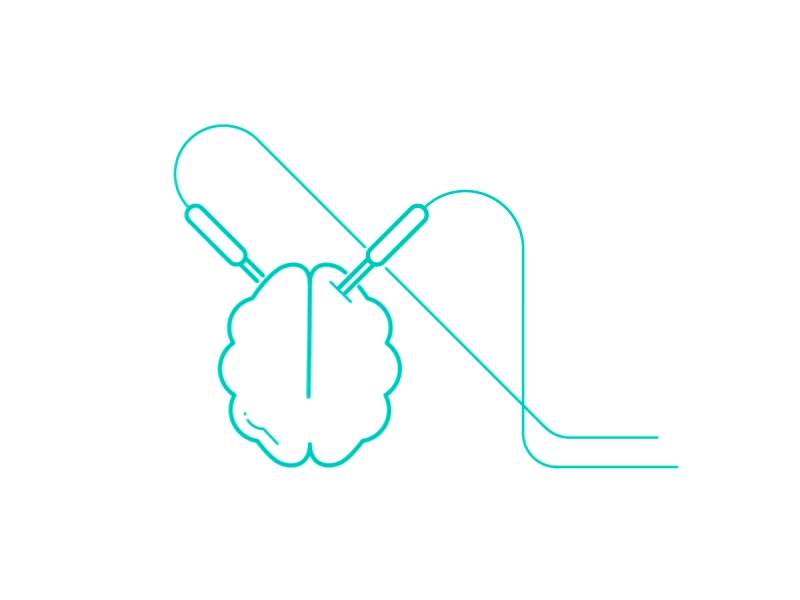

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['F:\DMSS\DMSS\RawData_new_new'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false ;
Deci.DCom               = false ; 
Deci.GCom               = false ; % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['F:\DMSS\DMSS\DMSSFullTrial'];        % Output Folder Directory

## 1. Trial Definitions 

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
%Deci.DT.Type =      'ABProb_Polymerase'; %comment out for any new subjects 
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                         % Cell Array of Markers for End codes.                   
Deci.DT.Markers    = {[11 21 31] [12 22 32] [25 35] [26 36] [39] [40] [43] [44] [50] [52 53 54] [61 62] [64 65] [72 73 74]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [260 261 50 57 60 70];  %260 = first stim onset all conds 261 = last stim offset all conds                                                           % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 5];    %[-2 5]                                                                % Time of Interest, be sure to include larger window for freq
Deci.DT.NanLocks = true;

% Deci.DT.Displace.Static = [52 54];
% Deci.DT.Displace.Markers = {[61 62] [64 65]};
% Deci.DT.Displace.Duration =2;
% Deci.DT.Displace.Num = -1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Markers   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.do = true;
Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 0];
% Deci.Art.RT.minlength = 200;
% Deci.Art.RT.locks = [3 2];

Deci.Art.ShowArt = true;
Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step > 3
    Deci.DT.Markers   = {[11 21 31] [12 22 32] [25 35] [26 36] [39] [40] [43] [44] [50] [52 53 54] [61 62] [64 65] [72 73 74] [1061 1062] [1064 1065] [2061 2062] [2064 2065] };                    
end

AnalysisTypes = {'DMSS_MedianSplitRT'};

AnalysisList = [true ];


## 5. Plotting

## ** 6. Run**

Running Deci for 18 subjects
 
----------------------
 
Plotting TotalPower
Loading Plottor for Subject #1: dmss01
Loading Plottor for Subject #2: dmss02
Loading Plottor for Subject #3: dmss03
Loading Plottor for Subject #4: dmss06
Loading Plottor for Subject #5: dmss07
Loading Plottor for Subject #6: dmss08
Loading Plottor for Subject #7: dmss09
Loading Plottor for Subject #8: dmss11
Loading Plottor for Subject #9: dmss13
Loading Plottor for Subject #10: dmss14
Loading Plottor for Subject #11: dmss15
Loading Plottor for Subject #12: dmss16
Loading Plottor for Subject #13: dmss17
Loading Plottor for Subject #14: dmss19
Loading Plottor for Subject #15: dmss20
Loading Plottor for Subject #16: dmss21
Loading Plottor for Subject #17: dmss24
Loading Plottor for Subject #18: dmss25
 
Using Lock: Delay Onset
Using Ref: Delay Onset at times -0.2-0
 
Calculating Statistics
using "ft_statistics_analytic" for the statistical testing
using "ft_statfun_depsamplesT" for the single-sample statistics


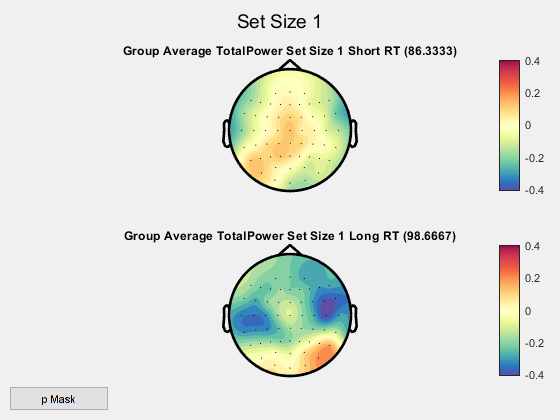

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds


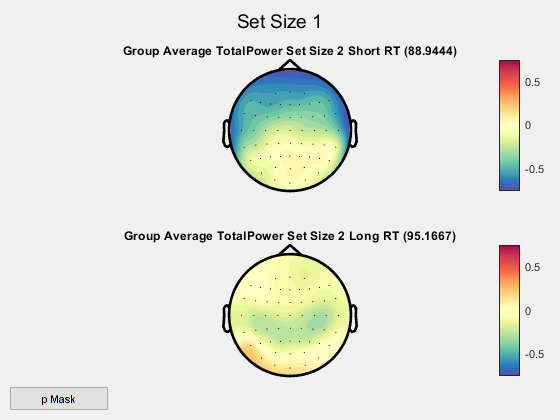

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds


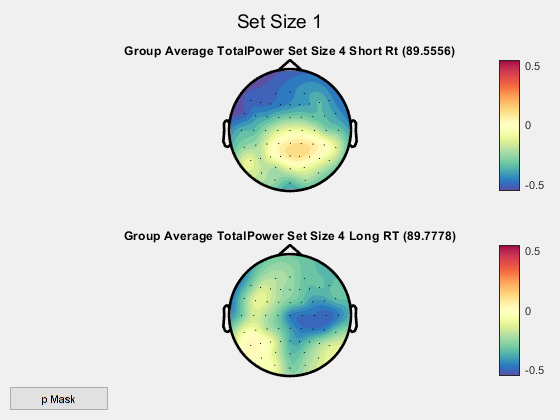

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
 
Calculating Statistics
using "ft_statistics_analytic" for the statistical testing
using "ft_statfun_depsamplesT" for the single-sample statistics
performing FDR correction for multiple comparisons
the returned probabilities are uncorrected, the thresholded mask is corrected
the call to "ft_freqstatistics" took 0 seconds
using "ft_statistics_analytic" for the statistical testing
using "ft_statfun_depsamplesT" for the single-sample statistics
performing FDR correction for multiple comparisons
the returned probabilities are uncorrected, the thresholded mask is corrected
the call to "ft_freqstatistics" took 0 seconds
using "ft_statistics_analytic" for the statistical testing
using "ft_statfun_depsamplesT" for t

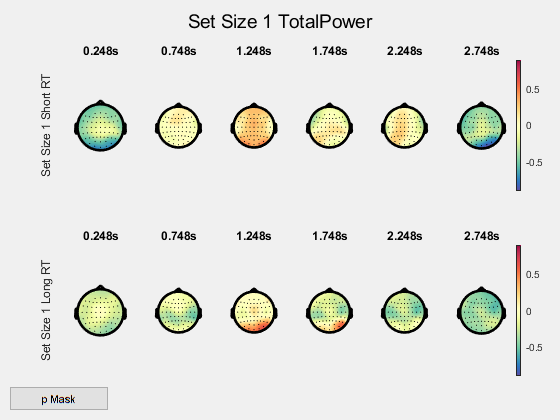

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layou

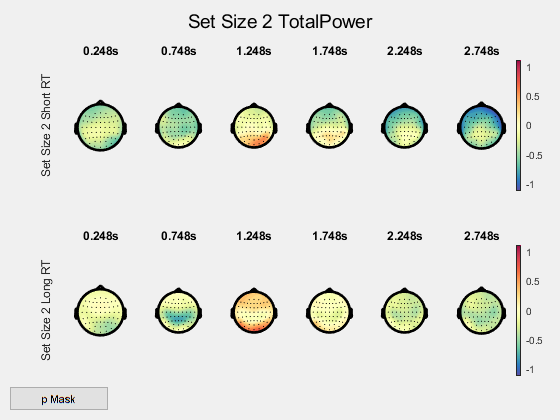

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layou

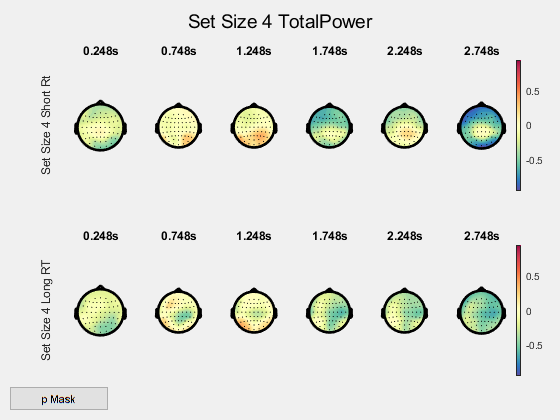

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layou

if Deci.Step == 4
    for AnalysisLocks = find(AnalysisList)
        Deci_Wavelet;
        
        
        Deci.Analysis.Freq.foi           = exp(linspace(log(3),log(60),40));  %change to 80                        % Frequency of Interest
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));   % Width
        Deci.Analysis.Toi           = [-.5 3];                                % [-.5 5]                  % Time Range to save
        Deci.Analysis.Toilim        = [-2 5]; %[-2 5]
        
        eval(AnalysisTypes{AnalysisLocks})
        Deci.SubjectList        = 'gui';
        Deci.Analysis.Freq.do  = true;
        Deci.Analysis.ERP.do  = false;          
        Deci_Backend(Deci);
        
    end
else
    
    DMSS_MedianSplitRT;
   
    Deci.Run.Behavior = false;
    Deci.Run.Freq =true;
    Deci.Run.ERP =false;
    Deci.Run.Extra = false; % for model, double, triplet, 2std
   
    Deci.Plot.BslRef =  'Delay Onset';
    Deci.Plot.Lock =  'Delay Onset' ;
    Deci.Plot.FreqYScale = 'linear';
    
    Deci.Plot.GrandAverage = true;
    Deci.Plot.GroupLevel =  false;
    Deci.Plot.Groups = {~[1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0] logical([1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0])};
    
    
    Deci.Plot.Topo.do    =true;
    Deci.Plot.Topo.Foi     = [8 12];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [1 3];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
     Deci.Plot.MTopo.do    =true;
    Deci.Plot.MTopo.Foi     = [8 12];                   % Frequency of Interest
    Deci.Plot.MTopo.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.MTopo.ToiSegs = 6;
    Deci.Plot.MTopo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =false;
    Deci.Plot.Square.Foi     = [4 30];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Foi     =   [13 20];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [0 3];                   % Time of Interest
    Deci.Plot.Wire.Channel = ['Reinhart-All'];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [4 7.5];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [];                   % Time of Interest
    Deci.Plot.Bar.Channel =  ['Reinhart-All'];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        %Deci.Plot.Bsl     = [-.5 -.3];
        Deci.Plot.Bsl     = [-.250 -.050];
    else
       % Deci.Plot.Bsl     = [-.5 0];
        Deci.Plot.Bsl     = [-.2 0];
        
    end
    
    if strcmpi(Deci.Plot.Freq.Type,'ITPC')
        Deci.Plot.Freq.Roi = 'maxmin';
    end
    
    
    
    if Deci.Run.Extra
        Deci.Plot.BslType = 'absolute';
        Deci.Plot.Roi = 'maxabs';
        Deci.Plot.Stat.do = true;
        Deci.Plot.ColorMap = CoolMap;
        
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.correctm = 'no';
        %         Omnibus = true;
        %
        %
        %         if Omnibus == true
        %             Deci.Plot.Stat.do = true;
        %             Deci.Plot.Stat.Comp = 'Bsl';
        %             Deci.Plot.Stat.alpha = .01;
        %             Deci.Plot.Stat.correctm = 'fdr';
        %             Deci.Plot.BslType = 'relchange';
        %             Deci.Plot.Stat.FPlots =  false;
        %         else
        %             Deci.Plot.Stat.do = true;
        %             Deci.Plot.Stat.Type = 'Randomize Permutation';
        %             Deci.Plot.Stat.alpha = .05;
        %             Deci.Plot.Stat.correctm = 'fdr';
        %         end
        %         Deci.Plot.Stat.FPlots =  false;
        
        
        
    elseif  Deci.Plot.Square.do
        Omnibus = true;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'db';
            Deci.Plot.Stat.Type = 'Anova/T-test';
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType ='db';
        end
        Deci.Plot.Stat.FPlots =  false;
       
    
    elseif Deci.Plot.Topo.do || Deci.Plot.MTopo.do
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
          %  Deci.Plot.Roi = [-.8 .8];
           
        end
    elseif Deci.Plot.Bar.do
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.FPlots =  false;
    elseif Deci.Plot.Wire.do
        Deci.Plot.Stat.do = true;
        Deci.Plot.Stat.Type = 'Anova/T-test';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.FPlots =  false;
        Deci.Plot.Stat.correctm = 'fdr';
    elseif Deci.Run.Extra
        Deci.Plot.BslType ='none';
    end
    
     Deci.Plot.Stat.twoway.do = false;
     Deci.Whatever =  false;
     
Deci_Backend(Deci);
end